# **JacobiOmega**

Periodic part of the Jacobi second form of the elliptic integral of the third kind

## Definition


$$\Omega \left(x,\nu \left|m\right.\right)\equiv \Lambda \left(x,\nu |m\right)-\frac{\Pi \left(\nu |m\right)}{K\left(m\right)}x$$



$$\Omega \left(x,\nu ,k\right)\equiv \Omega \left(x,\nu \left|k^2 \right.\right)$$


where x is an argument, $\nu$ is the characteristic, *k *is the modulus,  *m *is the parameter ,  $K\left(m\right)$ is the complete elliptic integral of the first kind, $\Pi \left(\nu \left|m\right.\right)$ is the  the complete elliptic integral of the third kind and $\Lambda \left(x,\nu \left|m\right.\right)$ is the Jacobi second form of elliptic integral of the third kind ([1]).

**Note. **Notation $$ and the name JacobiOmega are **not** standard. 

Domain:   If $-\infty <m\le 1$(or $\left.|k|\le 1\right)$ and and $-\infty <\nu <1$ then $-\infty \le x\le \infty$ . For the specified domain, the  codomain is the set of real numbers.

Basic features:

$\Omega \left(-x,\nu \left|m\right.\right)=-\Omega \left(x,\nu \left|m\right.\right)$   (odd)

 $\Omega \left(2n\;K\left(m\right)\pm x,\nu \left|m\right.\right)=\Omega \left(x,\nu \left|m\right.\right),\;\;\;\left|x\right|\le K\left(m\right)$  (periodic)

Special values:

$\Omega \left(0,\nu \left|m\right.\right)$,    $\Omega \left(x,0\left|m\right.\right)=0$,    $\Omega \left(x,0\left|0\right.\right)=0$  

Identities:

## Syntax

Y = JacobiOmega(X,NU,K)

y = jomega(x,nu,k)

Y = mJacobiOmega(X,NU,M)

y = mjomega(x,nu,m)

## Description

**Y = JacobiOmega(X,NU,K)** returns $\Omega \left(x,\nu ,k\right)$ for each element of the arrays X , NU (the characteristic) and K (the modulus). X, NU and K must be real and the same size or any of them can be scalar. **JacobiOmega** is the wrapper function which calls the functions **jomega** element-wise via the function **ufun3**.

**y = jomega(x,k) **returns $\Omega \left(x,\nu ,k\right)$ for the argument x, the characteristic nu and the modulus k. It is assumed that  the input arguments are real **scalars** without check. y is NaN if any of   the input arguments is invalid or convergence failed. **jomega** is the wrapper function which calls the functions **mjomega**.

**Y = mJacobiOmega(X,NU,M)** returns  $\Omega \left(x,\nu \left|m\right.\right)$  for each element of the arrays X (the argument), NU (the characteristic) and M (the parameter). X, NU and M must be real and the same size or any of them can be scalar. **mJacobiOmega** is the wrapper function which calls the functions **mjomega** element-wise via the function **ufun3**.

**y = mjomega(x,nu,m)** returns $\Omega \left(x,\nu \left|m\right.\right)$for  argument x, the characteristic nu and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mjomega **call the  function **mjlambda**, **mcelPi** and **melK **for calculation of $\Omega \left(x,\nu \left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
nu = 0.5;
x = 1;
[jomega(x,nu,k), JacobiOmega(x,nu,k), mjomega(x,nu,k^2), mJacobiOmega(x,nu,k^2)]

ans =   -0.260937472347740  -0.260937472347740  -0.260937472347740  -0.260937472347740


Accuracy. 


fprintf('%.16g\n',jomega(1,1/2,1/2)) 

-0.2609374723477402


%Maple -0.2609374723477402_1

Special values

m = -0.5;
nu = 0.5;
x = 10;
mJacobiOmega(-x,nu,m) + mJacobiOmega(x,nu,m)

ans = 0

mJacobiOmega(0,nu,m)

ans = 0

disp(mJacobiOmega(0,nu,m)-mJacobiOmega(mEllipticK(m),nu,m))

     0



**Vector input**

nu = [0.1, 0.2, 0.3];
m = [-1, -2,-3];
disp(mJacobiOmega(0,nu,m)-mJacobiOmega(mEllipticK(m),nu,m))

     0     0     0



**Matrix input**

nu = [0.1, 0.2; 0.3 0.5];
m = [-1, -2;-3, -5];
disp(mJacobiOmega(0,nu,m)-mJacobiOmega(mEllipticK(m),nu,m))

     0     0
     0     0



## **Graphs **

**Example 1**

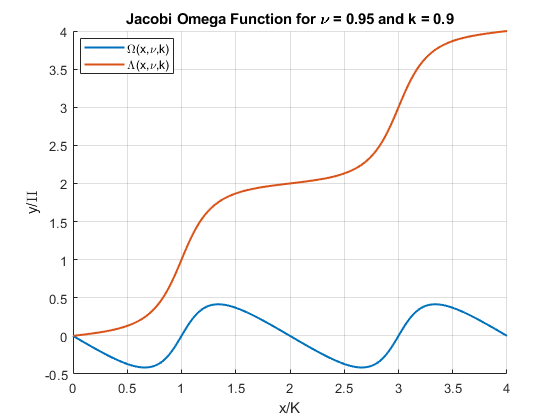

figure
hold on
x=0:0.01:4;
nu = 0.95;
k = 0.9;
s = elK(k);
P = elPi(nu,k);
plot(x,JacobiOmega(s*x,nu,k)/P,'LineWidth',1.5)
plot(x,JacobiLambda(s*x,nu,k)/P,'LineWidth',1.5)
xlabel('x/K')
ylabel('y/\Pi')
legend('\Omega(x,\nu,k)','\Lambda(x,\nu,k)','Location','best')
%ylim([-1,4])
title(sprintf('Jacobi Omega Function for %s = %g and k = %g','\nu',nu,k))
grid on

**Example 2**

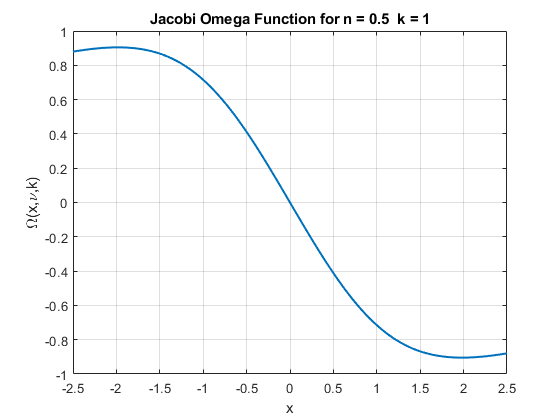

figure
x=-2.5:0.01:2.5;
nu = 1/2;
k = 0.99999991;
plot(x,JacobiOmega(x,nu,k),'LineWidth',1.5)
xlabel('x')
ylabel('\Omega(x,\nu,k)')
%xlim([-1.1 1.1])
%ylim([-2.2 2.2])
title(sprintf('Jacobi Omega Function for n = %g  k = %g',nu,k))
grid on

**Example 3**

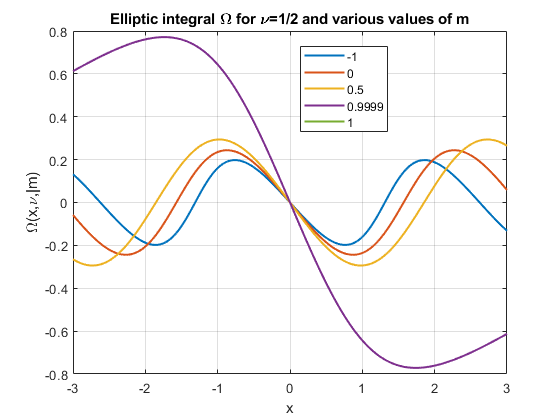

figure
X = -3:0.01:3;
nu = 0.5;
M = [-1,0,0.5,0.9999,1];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiOmega(X,nu,M(i));
end
plot(X,SN,'LineWidth',1.5)
%axis([min(X) max(X) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral \Omega for \nu=1/2 and various values of m')
xlabel('x')
ylabel('\Omega(x,\nu,|m)')

**Example 4**

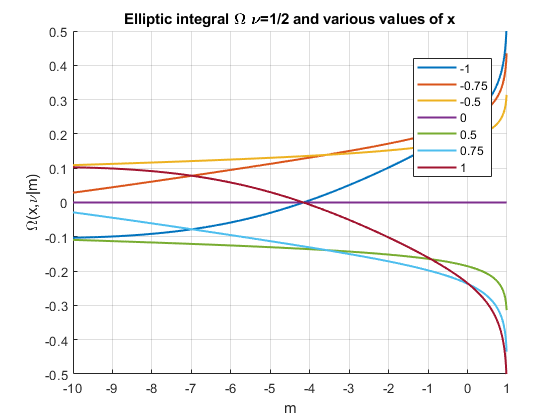

figure
hold on
nu = 0.5;
M = -10:0.01:1;
X = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mJacobiOmega(X(i),nu,M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -0.5 0.5])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral \Omega \nu=1/2 and various values of x')
xlabel('m')
ylabel('\Omega(x,\nu|m)')
hold off

**Example 5**

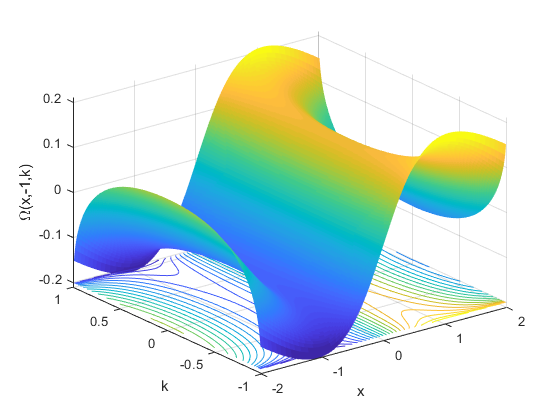

figure
x=-2:0.01:2;
k=-1:0.01:1;
nu = -1;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiOmega(X,nu,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -0.2;
hc.LineWidth = 0.5;
hc.LevelList = -0.2:0.02:0.2;
caxis([-0.2 0.2])
view(3);
xlabel('x')
ylabel('k')
zlabel('\Omega(x,-1,k)')
%zlim([-1 1])
grid on

**Example 6**

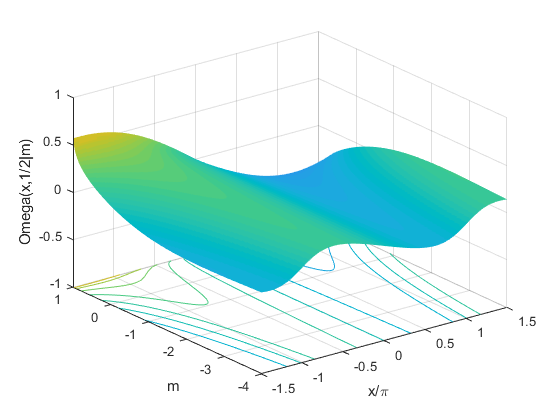

figure
x=-1.5:0.01:1.5;
m=-4:0.01:1;
nu = 1/2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mJacobiOmega(X,nu,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1;
hc.LineWidth = 0.5;
hc.LevelList = -1:0.1:1;
view(3)
caxis([-1 1])
xlabel('x/\pi')
ylabel('m')
zlabel('Omega(x,1/2|m)')
zlim([-1 1])
grid on

**Example 7**

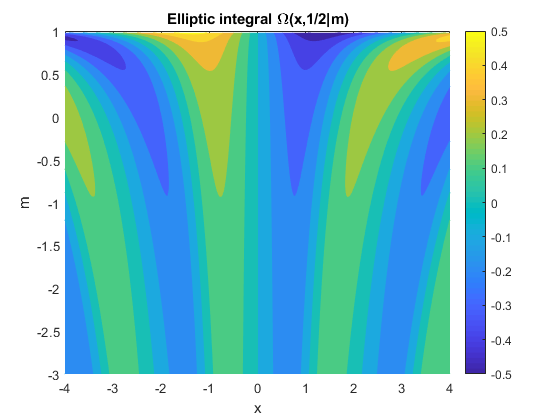

figure
nu = 0.5;
f = @(x,m)mJacobiOmega(x,nu,m);
fcontour(f,[-4 4 -3 1],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral \Omega(x,1/2|m)')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

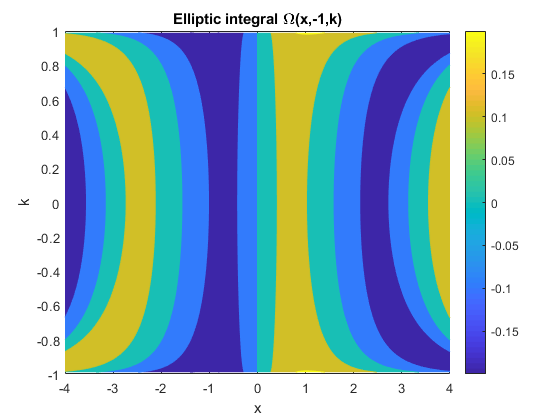

figure
nu = -1;
f = @(x,k)JacobiOmega(x,nu,k);
fcontour(f,[-4 4 -1 1],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral \Omega(x,-1,k)')
colorbar
xlabel('x')
ylabel('k')
grid on

**Example 9**

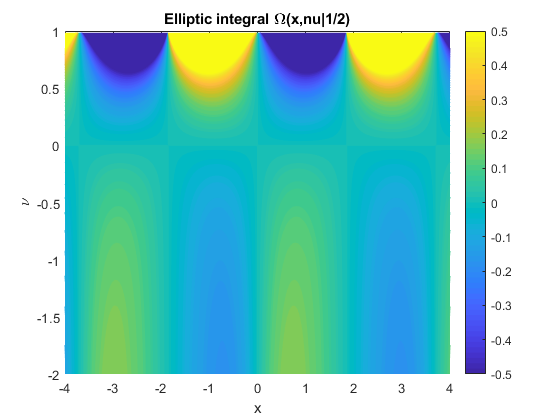

figure
m = 0.5;
f = @(x,nu)mJacobiOmega(x,nu,m);
fcontour(f,[-4 4 -2 1],'Fill','on','LevelList',-0.5:0.01:0.5,'MeshDensity',200)
title('Elliptic integral \Omega(x,nu|1/2)')
colorbar
xlabel('x')
ylabel('\nu')
grid on

**Example 10**

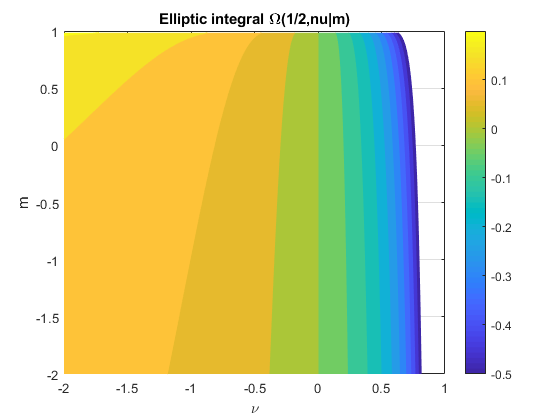

figure
x = 0.5;
f = @(nu,m)mJacobiOmega(x,nu,m);
fcontour(f,[-2 1 -2 1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Elliptic integral \Omega(1/2,nu|m)')
colorbar
xlabel('\nu')
ylabel('m')
grid on

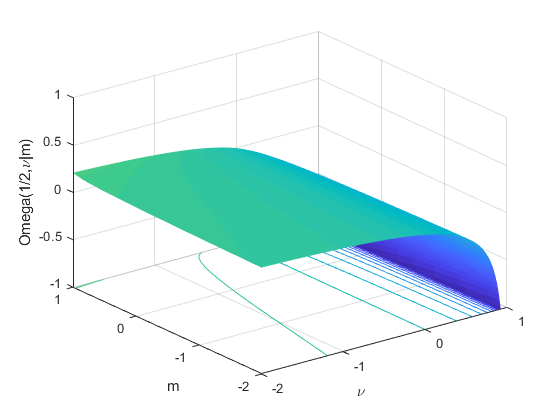

figure
x=0.5;
nu=-2:0.01:1;
m=-2:0.01:1;
[NU,M]=meshgrid(nu,m);
hs=surfc(NU,M,mJacobiOmega(x,NU,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1;
hc.LineWidth = 0.5;
hc.LevelList = -1:0.1:1;
view(3)
caxis([-1 1])
xlabel('\nu')
ylabel('m')
zlabel('Omega(1/2,\nu|m)')
zlim([-1 1])
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

[Higher Transcendental Functions](http://apps.nrbook.com/bateman/Vol2.pdf) 

## **References**

[1] R.G.Langebartel, "Fourier expansions of rational fractions of   elliptic integrals and Jacobian elliptic functions". SIAM  J. Math. Anal. 11, 3, 1980, pp 506-513

[2] D.F. Lawden, Elliptic functions and applications, Springer-Verlag, New York, 1989.

## See Also